E.T.S. Ingeniería Informática  Grado en Ingeniería de la Salud 

Ampliación de Matemáticas     Curso 2023/24 

## Práctica evaluable

Considere el siguiente problema: 

                
$$\frac{\partial^2 u}{\partial t^2} = c^2 \frac{\partial^2 u}{\partial x^2}, \quad x \in [0,L], t\in [0,T_f] $$


                
$$u(x,0)=\frac{x}{L}+sin(c\cdot x), \quad \frac{\partial u}{\partial t}(x,0)=1, \quad x \in [0,L]$$


                
$$u(0,t)=t, \qquad t \in (0,T_f]$$


                
$$\frac{\partial u}{\partial x} (L,t)=\frac{1}{L}+\frac{c}{2} \left( cos(c(L+ct))+cos(c(L-ct)) \right) \, \qquad t \in (0,T_f]$$
		

donde $c$ es una constante positiva. 

¿La función obtenida utilizando la fórmula de D'Alambert sin tener en cuenta las condiciones de contorno es solución de este problema? Determine su expresión.

Implemente esta solución en una función de Matlab (*solExacta*) que reciba como parámetros $c,T_f$, $L$ y el número de subintervalos en espacio,$M$, y tiempo,$N$, y devuelva los valores exactos en la partición equiespaciada del dominio correspondiente junto con los puntos de la partición en tiempo y en espacio.

Describa como resolvería este problema con los métodos de diferencias finitas y elementos finitos vistos en clase y escriba las funciones correspondientes en Matlab, DifFin y EleFin, con los mismos parámetros y resultados que *solExacta*.

Utilice estas funciones para resolver los problemas propuestos con$\;N$=$10,1000,\;$$M$=10 y 100, $c$= 0.5, 1 y 2, $T_f$=1 y $L$=2. Incluya aquí los resultados que le parezcan más interesantes para responder a las preguntas que se hacen a continuación.

En relación con la solución exacta: 

- ¿Cómo influye el valor de c en la solución?

*        El valor de c cambia la forma de la gráfica, dándole formas de mayor curvatura.*

En relación con el método de diferencias finitas: 

- ¿Ha observado algún problema de estabilidad? Si es así, ¿puede determinar alguna condición para los parámetros que asegure la estabilidad? ¿Influye el valor de c en la condición de estabilidad?

*        El método de DF es estable en casi todos los casos experimentales.*

- ¿Cómo influyen los valores de $M$ y $N$ en los resultados obtenidos?

 *       Tanto experimentalmente como según Von Neumann, DF es estable siempre y cuando At no sea mayor que Ax.*


$$\frac{\Delta t\sqrt{c^2+1}}{\Delta x c} \le 1$$


- ¿Cree que son buenos los resultados obtenidos?

*        El método parece bastante bueno.*

En relación con el método de elementos finitos:

- ¿Qué método ha elegido para resolver el problema de valores iniciales en $t$? ¿Por qué? 

*        He elegido el método de Euler Explícito, porque fue el que se propuso en clase y porque muestra un mayor contraste en los resultados, diferenciando los métodos de forma clara.*

- ¿Cómo influyen los valores de $M$ y $N$ en los resultados obtenidos?

*        El método es estable cuando N es menor que M y para valores de c menores o iguales que 1.*

-  ¿Cree que son buenos los resultados obtenidos?

*        Creo que se podría obtener una mayor estabilidad con otros métodos, como Euler Implícito.*

*PRUEBAS MÁS RELEVANTES REALIZADAS PARA SACAR CONCLUSIONES*

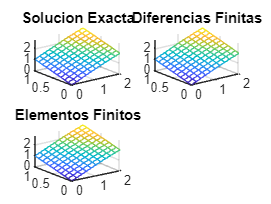

% Prueba base
figure
c=0.5;
L=2;
Tf=1;
M=10;
N=10;
[xex,tex,yex]=solExacta(c,L,Tf,M,N);

subplot(221)
mesh(xex,tex,yex)
title('Solucion Exacta')

[xdf,tdf,ydf]=DifFin(c,L,Tf,M,N);

subplot(222)
mesh(xdf,tdf,ydf)
title('Diferencias Finitas')

[xef,tef,yef]=EleFin(c,L,Tf,M,N);

subplot(223)
mesh(xef,tef,yef)
title('Elementos Finitos')

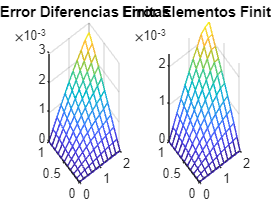


figure
subplot(121)
mesh(xdf,tdf,ydf-yex);
title('Error Diferencias Finitas')
subplot(122)
mesh(xef,tef,yef-yex);
title('Error Elementos Finitos')

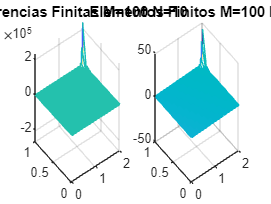



% Con M=100 y N=10 DF y EF no son estables

M=100;
N=10;

[xdf,tdf,ydf]=DifFin(c,L,Tf,M,N);

figure

subplot(121)
mesh(xdf,tdf,ydf)
title('Diferencias Finitas M=100 N=10')

[xef,tef,yef]=EleFin(c,L,Tf,M,N);

subplot(122)
mesh(xef,tef,yef)
title('Elementos Finitos M=100 N=10')

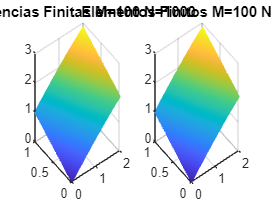


% Con M=100 y N=1000 ambas son estables, aunque el error aumenta

M=100;
N=1000;

[xdf,tdf,ydf]=DifFin(c,L,Tf,M,N);

figure

subplot(121)
mesh(xdf,tdf,ydf)
title('Diferencias Finitas M=100 N=1000')

[xef,tef,yef]=EleFin(c,L,Tf,M,N);

subplot(122)
mesh(xef,tef,yef)
title('Elementos Finitos M=100 N=1000')

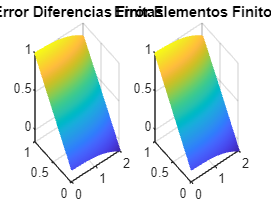



[yex]=solExacta(c,L,Tf,M,N);

figure
subplot(121)
mesh(xdf,tdf,ydf-yex);
title('Error Diferencias Finitas')
subplot(122)
mesh(xef,tef,yef-yex);
title('Error Elementos Finitos')

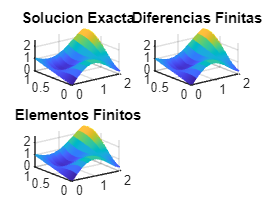


% El valor de c afecta a la estabilidad del método de EF pero no al método
% de DF. Según la teoría, cuanto mayor sea el valor de c, menos debe
% afectar a la estabilidad de DF.

figure
c=2;
L=2;
Tf=1;
M=10;
N=1000;
[xex,tex,yex]=solExacta(c,L,Tf,M,N);

subplot(221)
mesh(xex,tex,yex)
title('Solucion Exacta')

[xdf,tdf,ydf]=DifFin(c,L,Tf,M,N);

subplot(222)
mesh(xdf,tdf,ydf)
title('Diferencias Finitas')

[xef,tef,yef]=EleFin(c,L,Tf,M,N);

subplot(223)
mesh(xef,tef,yef)
title('Elementos Finitos')

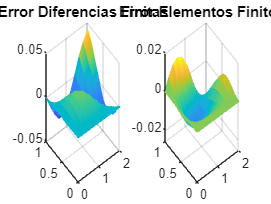


figure
subplot(121)
mesh(xdf,tdf,ydf-yex);
title('Error Diferencias Finitas')
subplot(122)
mesh(xef,tef,yef-yex);
title('Error Elementos Finitos')

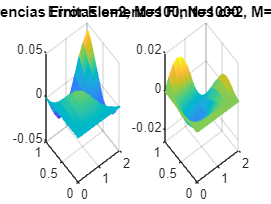



figure
subplot(121)
mesh(xdf,tdf,ydf-yex);
title('Error Diferencias Finitas c=2, M=100, N=1000')
subplot(122)
mesh(xef,tef,yef-yex);
title('Error Elementos Finitos c=2, M=100, N=1000')


% Pruebas

figure
c=2;
L=2;
Tf=1;
M=10;
N=1000;
[xex,tex,yex]=solExacta(c,L,Tf,M,N);

subplot(221)
mesh(xex,tex,yex)
title('Solucion Exacta')

[xdf,tdf,ydf]=DifFin(c,L,Tf,M,N);

subplot(222)
mesh(xdf,tdf,ydf)
title('Diferencias Finitas')

[xef,tef,yef]=EleFin(c,L,Tf,M,N);

subplot(223)
mesh(xef,tef,yef)
title('Elementos Finitos')


figure
subplot(121)
mesh(xdf,tdf,ydf-yex);
title('Error Diferencias Finitas')
subplot(122)
mesh(xef,tef,yef-yex);
title('Error Elementos Finitos')

FUNCIONES PEDIDAS

% solExacta

function [x,t,y]=solExacta(c,L,Tf,M,N)

ax=L./M;
at=Tf/N;
x=0:ax:L;
t=0:at:Tf;
[X,TP]=meshgrid(x,t);
y=X/L+(sin(c*X+c^2*TP)+sin(c*X-c^2*TP))/2+TP;
end

% DifFin

function [x,t,y]=DifFin(c,L,Tf,M,N)

ax=L./M;
at=Tf/N;
r=at^2/ax^2;
x=0:ax:L;
t=0:at:Tf;
m=length(x);
n=length(t);
A=(2.-2*c^2*r)*eye(m-1)+r*c^2*diag(ones(m-2,1),1)+r*c^2*diag(ones(m-2,1),-1);
%length(A)
A(M,M-1)=2*A(M,M-1);
B=zeros(1,M);

y=zeros(n,m);
%length(y)
y(:,1)=t;
y(1,:)=x/L+sin(c*x);
y(2,:)=y(1,:)+at;

for j=2:N
    B(1,1)=c^2*r*t(j);
    B(1,M)=c^2*r*(2*ax/L+c*ax*(cos(c*L+c^2*t(j))+cos(c*L-c^2*t(j))));
    y(j+1,2:m)=(A*y(j,2:m)'-y(j-1,2:m)'+B')';

end

end

% EleFin

function [x,t,y]=EleFin(c,L,Tf,M,N)
% u solución aproximada del problema u_t =c u_xx x in (0,2), t in (0,Tf)
% c.i y c.c. especificadas en enunciado
% en x partición con M subintervalos del intervalo [0,2]
% y t partición con N subintervalos del intervalo [0,Tf]
% obtenida con un método de elementos finitos
ax=L/M;
at=Tf/N;
x=0:ax:L;
t=0:at:Tf;
m=length(x);
n=length(t);
c1=2./ax;
c2=-1./ax;
a1=2.*ax/3.;
a2=ax/6.;
A=a1*eye(m-1)+a2*diag(ones(m-2,1),1)+a2*diag(ones(m-2,1),-1);
A(m-1,m-1)=A(m-1,m-1)/2;

B=-c^2*(c1*eye(m-1)+c2*diag(ones(m-2,1),1)+c2*diag(ones(m-2,1),-1));
B(m-1,m-1)=B(m-1,m-1)/2;

F=A\B;
C=zeros(m-1,1);

% resolvemos U'=(A\B)U+A\C con Euler explicito

y=ones(n,m);
y(1,:)=x/L+sin(c.*x);
y(:,1)=t;

P=[zeros(m-1,m-1) eye(m-1); F zeros(m-1,m-1)];

z=zeros(n,2*(m-1));
z(1,1:m-1)=y(1,2:m);
z(1,m:2*(m-1))=1;

for k=1:N
    
    f=1/L+c/2*(cos(c*L+c^2*t(k))+cos(c*L-c^2*t(k)));

    C(m-1)=c^2*f;
    C(1)=c^2*t(k)/ax;
    z(k+1,:)=(z(k,:)'+at*(P*z(k,:)'+[zeros(m-1,1); A\C]))';
    y(k+1,2:m)=z(k+1,1:m-1);

end


end